# tlModel

Script to compare various TL model options

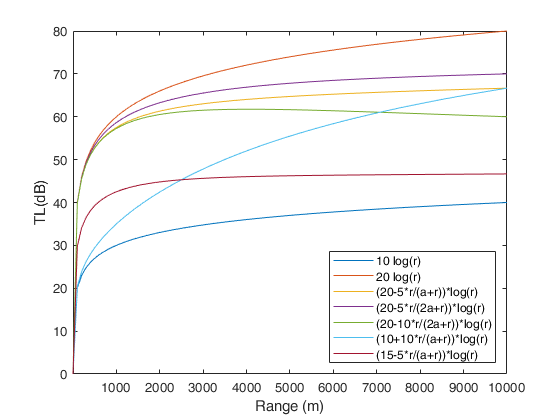

clear
% syms r
r = linspace(1e0,1e4,101);
a = 5e3;

% lin = (a+r);
% TL1 = (15+(5.*r./))
TL1 = (20-(5.*r./(a+r)));
% TL1 = 10*log10(r);
% TL2 = 20*log10(r);
% TL1 = (20-(10*r/(a+r)))*log10(r);


f=figure;
ax=axes;
plot(r,10*log10(r),"DisplayName","10 log(r)")
hold on
plot(r,20*log10(r),"DisplayName","20 log(r)")
%plot(r,y1);%,"DisplayName","(10+10*r/(a+r))*log(r)")
%plot(r,(15+(5.*r/(a+r)))*log10(r),"DisplayName","(15+5*r/(a+r))*log(r)")
%plot(r,TL1,"DisplayName","(15+5*r/(a+r))*log(r)")
plot(r,(20-(5.*r./(a+r))).*log10(r),"DisplayName","(20-5*r/(a+r))*log(r)")
plot(r,(20-(5.*r./(2*a+r))).*log10(r),"DisplayName","(20-5*r/(2a+r))*log(r)")
plot(r,(20-(10.*r./(2*a+r))).*log10(r),"DisplayName","(20-10*r/(2a+r))*log(r)")
plot(r,(10+(10.*r./(a+r))).*log10(r),"DisplayName","(10+10*r/(a+r))*log(r)")
plot(r,(15-(5.*r./(a+r))).*log10(r),"DisplayName","(15-5*r/(a+r))*log(r)")
xlabel("Range (m)")
ylabel("TL(dB)")
legend("Location","Southeast")
%ax.XScale = 'log';
ax.XLim = [1 max(r)];